clc, clear, close all
rng(100);           
run('definitions.m');

VLP definitions and parameters loaded successfully


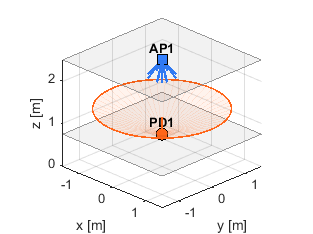


mode = 'one_beamsteering_LED';
AP = AP_config.(mode);
run('fig_setup.m') % ===> MEJORAR LA FUNCION PARA Q SE MUETREN LAS ORIETNACIONS


% channel.sigma2 = 0;

Nsamples = 100;     % muestras por posición y por AP
S_min = 1e-12 ; % evitar potencias negativas

% Ground truth positions
xv = testbed.x(1):testbed.gridstep:testbed.x(2);
yv = testbed.y(1):testbed.gridstep:testbed.y(2);
[X, Y] = meshgrid(xv, yv);

Npos = numel(X);
Nori = size(AP(1).set_n_t, 1);
Nap  = numel(AP);
S_r  = cell(Npos, Nap, Nori);
SNR  = cell(Npos, Nap, Nori);

for i_pos = 1:Npos
    UE.pos(1:2) = [X(i_pos), Y(i_pos)];
    UE.n_r = -angles2vec([randi(UE.delta_tilt+1)-1, randi(360)]); % error:PD tilt
    
    for i_ap = 1:Nap
        for i_ori = 1:Nori
            AP(i_ap).n_t = angles2vec( AP(i_ap).set_n_t(i_ori,:) );
            h0 = h_LOS(AP(i_ap), UE, channel.model);
            S_0 = UE.R_pd * AP(i_ap).P_t * h0;
            w_noise  = sqrt(channel.sigma2) * randn(1, Nsamples);
            S_samples = S_0 + w_noise;
            S_samples = max(S_samples, S_min);
            S_r{i_pos, i_ap, i_ori} = S_samples;
            SNR{i_pos, i_ap, i_ori} = 10*log10( S_0^2 / channel.sigma2);
        end
    end
end

SNR_mean_AP1 = mean(cellfun(@(x) mean(x), SNR(:,:,1)));
fprintf('SNR mean AP1 %.1f dB', SNR_mean_AP1);

SNR mean AP1 19.1 dB

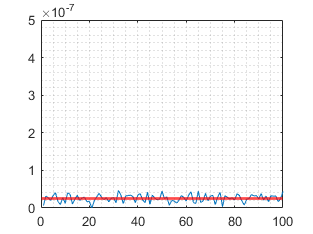


figure
plot(S_0 + w_noise)
yline(S_0,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

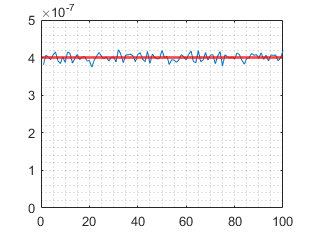


S_r_max = 4e-7;
figure
plot(S_r_max + w_noise)
yline(S_r_max,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

**One Orientation**

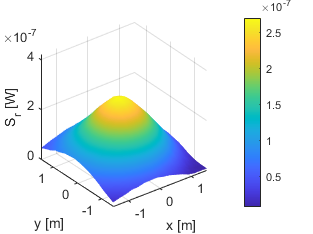

figure
S_r_mean_AP1 = cellfun(@(x) mean(x), S_r(:,:,1));
surf(X, Y, reshape(S_r_mean_AP1, size(X)));
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
shading interp; colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 4.2e-7])

**Obtaining the mean**

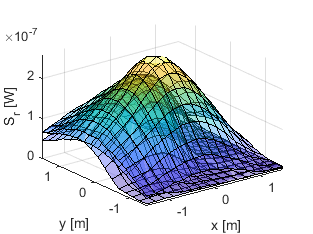

S_r_mean = zeros(Npos, Nap, Nori);
for i_ap = 1:Nap
    for i_ori = 1:Nori
        S_r_mean(:, i_ap, i_ori) = cellfun(@(x) mean(x), S_r(:, i_ap, i_ori));
    end
end

figure
surf(X, Y, reshape(S_r_mean(:,1,1), size(X)),FaceAlpha=0.4);
hold on
surf(X, Y, reshape(S_r_mean(:,1,2), size(X)),FaceAlpha=0.4);
surf(X, Y, reshape(S_r_mean(:,1,3), size(X)),FaceAlpha=0.4);
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
%shading interp; %colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 2.6e-7])

**Projection in 2D**

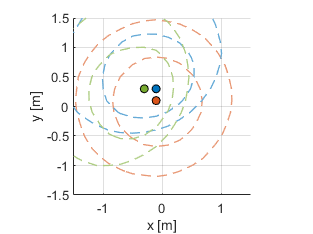

figure
hold on

alpha_val = 0.6;  
colors = [ 0.85 0.33 0.10;  
           0.00 0.45 0.74;  
           0.47 0.67 0.19]; 

bg = [1 1 1];
blend = @(c,a) (1-a)*bg + a*c;
c1 = blend(colors(1,:), alpha_val);
c2 = blend(colors(2,:), alpha_val);
c3 = blend(colors(3,:), alpha_val);

contour(X, Y, reshape(S_r_mean(:,1,1), size(X)), 2, 'LineWidth', 1, 'LineColor', c1, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,1,2), size(X)), 2, 'LineWidth', 1, 'LineColor', c2, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,1,3), size(X)), 2, 'LineWidth', 1, 'LineColor', c3, 'LineStyle','--');

for k = 1:3
    Z = reshape(S_r_mean(:,1,k), size(X));
    [~, idx] = max(Z(:));
    plot(X(idx), Y(idx), 'o', 'MarkerFaceColor', colors(k,:), 'MarkerEdgeColor', 'k');
end

hold off
xlabel('x [m]'); ylabel('y [m]');
grid on
axis equal tight

**Model-based estimation (using only 1 set of 3 orientation)**

est_pos = zeros(Npos, 2);   % (x_est, y_est)
true_pos = [X(:), Y(:)];

for i_pos = 1:Npos
    
    S_r_i = squeeze(S_r_mean(i_pos, 1, :)); % AP=1
    h_vert = AP.pos(3)-UE.pos(3);

    try
        n_d = estimate_direction(S_r_i', angles2vec(AP.set_n_t), AP.m_opt, 'svd');
        escale = -h_vert/n_d(3);
        est_pos(i_pos,:) = AP.pos(1:2) + escale*n_d(1:2);
    catch
        est_pos(i_pos,:)= [NaN, NaN];
    end

end

**Show results**

APE  : 67.726 cm
RMSE : 85.932 cm
CDF_90 : 135.542 cm


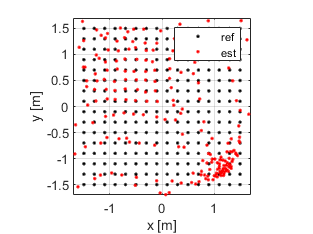

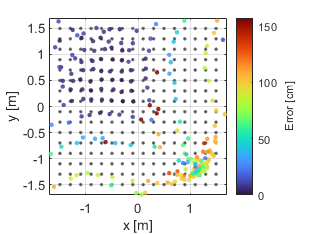

run('show_metrics.m');

**Estimation with set per area (Q)**

APE  : 5.325 cm
RMSE : 6.548 cm
CDF_90 : 10.252 cm


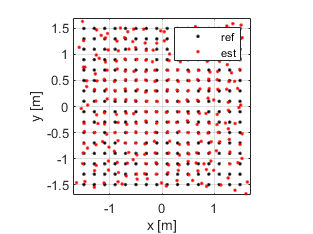

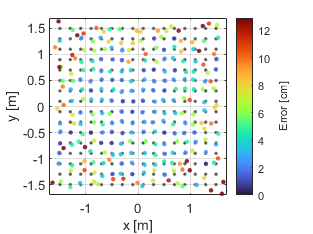

est_pos = zeros(Npos, 2);   % (x_est, y_est)
true_pos = [X(:), Y(:)];

Q1 = [-1.5  0.0   0.0  1.5];
Q2 = [ 0.0  1.5   0.0  1.5];
Q3 = [-1.5  0.0  -1.5  0.0];
Q4 = [ 0.0  1.5  -1.5  0.0];
Q = [Q1;Q2;Q3;Q4];

for i_pos = 1:Npos
    
    S_r_i = squeeze(S_r_mean(i_pos, 1, :))'; % AP=1
    h_vert = AP.pos(3)-UE.pos(3);
    
    for iQ = 1:4
        
        tp = true_pos(i_pos,:);
        x = tp(1); y=tp(2);
        if x < 0 && y >= 0
            area = 'Q1';
            set_Q = angles2vec(AP.set_n_t(1:3,:));
            S_r_i_Q = S_r_i(1:3);
        elseif x >= 0 && y >= 0
            area = 'Q2';
            set_Q = angles2vec(AP.set_n_t(4:6,:));
            S_r_i_Q = S_r_i(4:6);
        elseif x < 0 && y < 0
            area = 'Q3';
            set_Q = angles2vec(AP.set_n_t(7:9,:));
            S_r_i_Q = S_r_i(7:9);
        elseif x >= 0 && y < 0
            area = 'Q4';
            set_Q = angles2vec(AP.set_n_t(10:12,:));
            S_r_i_Q = S_r_i(10:12);
        else 
            area = 'Fuera'
        end

        try
            n_d = estimate_direction(S_r_i_Q, set_Q , AP.m_opt, 'svd');
            escale = -h_vert/n_d(3);
            est_pos(i_pos,:) = AP.pos(1:2) + escale*n_d(1:2);
        catch
            est_pos(i_pos,:)= [NaN, NaN];
        end
    end
end
run('show_metrics.m');